% Load the neural network for the simple pendulum
load('net.mat')
load('test_data_simple_cell.mat');
load('test_data_simple.mat');

netSimple = net;

% Setting up plotting parameters
start_simple = 1;
numSimulations_simple = 10;
data_simple = test_data_simple_cell;
data_simple_struct = test_data_simple;

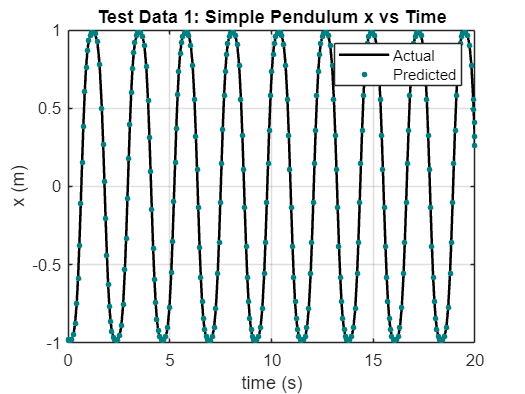

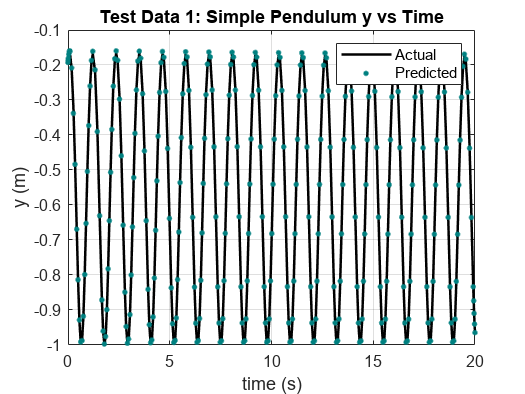

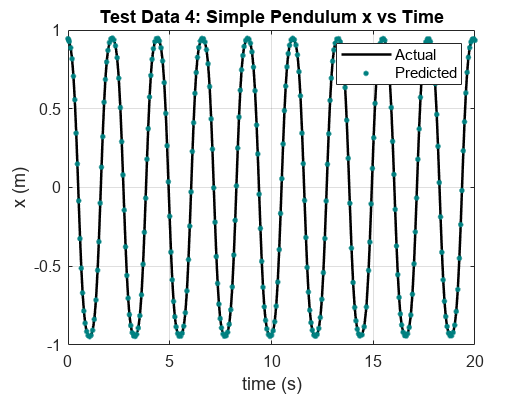

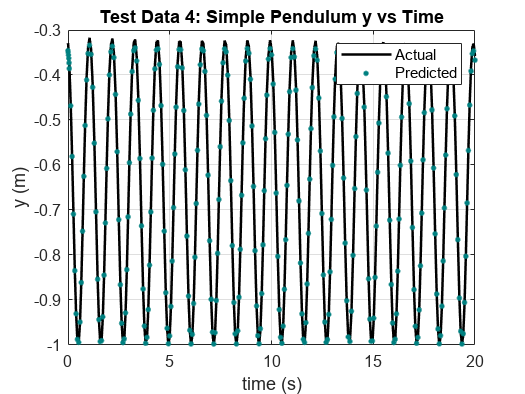

% Loop through the specified simulations for plotting
for i_simple = [1 4] %start_simple:numSimulations_simple
    % Extracting data for the current simulation
    time_simple = data_simple{i_simple, 1};
    x_simple = data_simple{i_simple, 4};
    y_simple = data_simple{i_simple, 5};
    
    % Transposing the data     

    inputX_simple = x_simple';
    inputY_simple = y_simple';

    % Making predictions using the neural network       

    predictedX_simple = predict(netSimple, {inputX_simple});
    predictedY_simple = predict(netSimple, {inputY_simple});
   
    % Converting predicted data to matrices   

    newPredictedX_simple = cell2mat(predictedX_simple);
    newPredictedY_simple = cell2mat(predictedY_simple);


    newPredictedX_simple = newPredictedX_simple';
    newPredictedY_simple = newPredictedY_simple';



    % Plotting X against Time
    figure;
    plot(time_simple, x_simple, 'k', 'LineWidth', 1.5); % Black for Actual
    hold on;                
    plot(time_simple, newPredictedX_simple, 'color', [0, 0.5, 0.5], 'LineStyle', 'none', 'Marker', '.', 'MarkerSize', 10);  
    xlabel('time (s)');
    ylabel('x (m)');
    title(['Test Data ', num2str(i_simple), ': Simple Pendulum x vs Time'])
    legend('Actual', 'Predicted');
    grid on;
    hold off;

   

    % Plotting Y against Time
    figure;
    plot(time_simple, y_simple, 'k', 'LineWidth', 1.5); % Black for Actual
    hold on;
    plot(time_simple, newPredictedY_simple, 'color', [0, 0.5, 0.5],'LineStyle', 'none', 'Marker', '.', 'MarkerSize', 10);  
    xlabel('time (s)');
    ylabel('y (m)');
    title(['Test Data ', num2str(i_simple), ': Simple Pendulum y vs Time'])
    legend('Actual', 'Predicted');
    grid on;
    hold off;
   
end

% Save all figures into a single MAT-file
save('SP_Trajectory_figures.mat', 'figHandles_x_Position','figHandles_y_Position');

Error using save
Variable 'figHandles_y_Position' not found.

% To load the figures later, you can use:
% 1. Load the MAT-file
loadedData = load('SP_Trajectory_figures.mat');

% 2. Access the figure handles from the loaded data
loadedFigHandles_x_Position = loadedData.figHandles_x_Position;
loadedFigHandles_y_Position = loadedData.figHandles_y_Position;

% 3. Display the figures
for i_simple = [1 4]%start_simple:numSimulations_simple
    figure(loadedFigHandles_x_Position{i_simple});
    figure(loadedFigHandles_y_Position{i_simple});
end